# Victoria Strobel 

## Fahrzeugdaten laden

FzgDaten;

FzgDaten geladen


## Längsdynamik

### Simulation Bremsvorgang

Das Simulink-Modell *Bremsvorgang* simuliert einen Bremsvorgang bei Geradeausfahrt für folgendes Zustandsraum-Modell:


$$\left[\matrix{ \dot{s} \cr \dot{v}} \right] = \left[\matrix{ 0 & 1 \cr 0 & 0} \right] \left[\matrix{ s \cr v} \right] + \left[\matrix{ 0 \cr 1} \right] a_x$$



$$y = \left[\matrix{ 1 & 0 \cr 0 & 1} \right] \left[\matrix{ s \cr v} \right]$$


Zunächst werden die Eingangsdaten $T_0$, $T_1$, $T_2$, $a_{x1}$ und $a_{x2}$ auf realistische Werte gesetzt.

T0 = 0.6;
T1 = 0.4;
T2 = 0.2;
ax1 = -1;
ax2 = -9;

model = 'Bremsvorgang';
load_system(model)
simIn = Simulink.SimulationInput(model);
simIn = setModelParameter(simIn,...
    'SolverType','Fixed-step',...
    'FixedStep','0.01');
simIn = setBlockParameter(simIn, "Bremsvorgang/Repeating_Sequence", "rep_seq_t", mat2str([0 T0 T0+T1 T0+T1+T2 20]));
simIn = setBlockParameter(simIn, "Bremsvorgang/Repeating_Sequence", "rep_seq_y", mat2str([0 0 ax1 ax2 ax2]));

Bremsvorgang simulieren:

out = sim(simIn);

Daten auslesen:

outputs = out.yout;
t_output = out.tout;
v_output = getElement(outputs, "v").Values.Data;
s_output = getElement(outputs, "s").Values.Data;
a_output = -getElement(outputs, "a").Values.Data;

t = downsample(t_output, round(length(t_output)/250));
s = downsample(s_output, round(length(s_output)/250));
v = downsample(v_output, round(length(v_output)/250));
a = downsample(a_output, round(length(a_output)/250));

index_t0 = find(t == T0);
index_t1 = find(t == round(T0+T1, 1));
index_t2 = find(t == round(T0+T1+T2, 1));
index_t3 = find(t == t(end)-1);

Daraus lässt sich ein DIagramm nach *Abbildung 1.25* erzeugen.

Darstellung der Beschleunigung $a$ über der Zeit $t$:

figure
subplot(3,1,1);
plot(t,a)
box off
axis on
hold on
pbaspect([2 1 1])
xlabel("Zeit $t$ $[s]$", 'Interpreter','latex')
ylabel('Fahrzeugverz\"ogerung $a$ $[\frac{m}{s^2}]$','Interpreter','latex')
title ('Verlauf der Fahrzeugverz\"ogerung', 'Interpreter','latex');
ylim([min(a), max(a)+1])
xlim([0, t(end)])

plot([t(index_t1), t(index_t1)], [0, a(index_t1)], 'k')
plot([t(index_t2), t(index_t2)], [0, a(index_t2)], 'k')
plot([t(index_t3), t(index_t3)], [0, a(index_t3)], 'k')

text(T0*0.5, 0.5, '$T_0$', 'HorizontalAlignment', 'center', 'Interpreter', 'latex');
text(T0+T1*0.5, 0.5, '$T_1$', 'HorizontalAlignment', 'center', 'Interpreter', 'latex');
text(T0+T1+T2*0.5, 0.5, '$T_2$', 'HorizontalAlignment', 'center', 'Interpreter', 'latex');
text(T0+T1+T2+(t(index_t3)-(T0+T1+T2))/2, 0.5, '$T_3$', 'HorizontalAlignment', 'center', 'Interpreter', 'latex');

plot([0, t(index_t1)], [a(index_t1), a(index_t1)], 'k')
plot([0, t(index_t2)], [a(index_t2), a(index_t2)], 'k')

text(0.1, a(index_t1)+0.5, '$a_{x1}$', 'Interpreter', 'latex')
text(0.1, a(index_t2)+0.5, '$a_{x2}$', 'Interpreter', 'latex')

hold off

Darstellung der Geschwindigkeit $v$ über der Zeit $t$:

subplot(3,1,2);
plot(t,v)
hold on
box off
axis on
pbaspect([2 1 1])
xlabel("Zeit $t$ [s]", 'Interpreter','latex')
ylabel("Fahrgeschwindigkeit $v$ $[\frac{m}{s}]$", 'Interpreter','latex')
title ('Verlauf der Fahrgeschwindigkeit', 'Interpreter','latex');
ylim([min(v), max(v)+1])
xlim([0, t(end)])

xline(t(index_t0))
xline(t(index_t1))
xline(t(index_t2))
xline(t(index_t3))

text(T0*0.5, 1.0, '$T_0$', 'HorizontalAlignment', 'center', 'Interpreter', 'latex');
text(T0+T1*0.5, 1.0, '$T_1$', 'HorizontalAlignment', 'center', 'Interpreter', 'latex');
text(T0+T1+T2*0.5, 1.0, '$T_2$', 'HorizontalAlignment', 'center', 'Interpreter', 'latex');
text(T0+T1+T2+(t(index_t3)-(T0+T1+T2))/2, 1.0, '$T_3$', 'HorizontalAlignment', 'center', 'Interpreter', 'latex');

plot([0, t(index_t1)], [v(index_t1), v(index_t1)], 'k')
plot([0, t(index_t2)], [v(index_t2), v(index_t2)], 'k')

text(0.1, v(index_t1)+0.5, '$v_1$', 'Interpreter', 'latex')
text(0.1, v(index_t2)+0.5, '$v_2$', 'Interpreter', 'latex')
hold off

Darstellung der Strecke $s$ über der Zeit $t$:

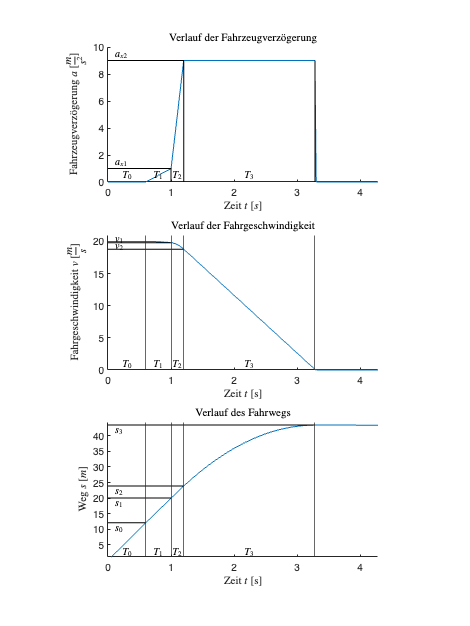

subplot(3,1,3);
plot(t,s)
hold on
box off
axis on
pbaspect([2 1 1])
xlabel("Zeit $t$ [s]", 'Interpreter','latex')
ylabel("Weg $s$ $[m]$", 'Interpreter','latex')
title ('Verlauf des Fahrwegs', 'Interpreter','latex');
ylim([min(s), max(s)]+1)
xlim([0, t(end)])
xline(t(index_t0))
xline(t(index_t1))
xline(t(index_t2))
xline(t(index_t3))

plot([0, t(index_t0)], [s(index_t0), s(index_t0)], 'k')
plot([0, t(index_t1)], [s(index_t1), s(index_t1)], 'k')
plot([0, t(index_t2)], [s(index_t2), s(index_t2)], 'k')
plot([0, t(index_t3)], [s(index_t3), s(index_t3)], 'k')

text(T0*0.5, 2.5, '$T_0$', 'HorizontalAlignment', 'center', 'Interpreter', 'latex');
text(T0+T1*0.5, 2.5, '$T_1$', 'HorizontalAlignment', 'center', 'Interpreter', 'latex');
text(T0+T1+T2*0.5, 2.5, '$T_2$', 'HorizontalAlignment', 'center', 'Interpreter', 'latex');
text(T0+T1+T2+(t(index_t3)-(T0+T1+T2))/2, 2.5, '$T_3$', 'HorizontalAlignment', 'center', 'Interpreter', 'latex');

text(0.1, s(index_t0)-1.5, '$s_0$', 'Interpreter', 'latex')
text(0.1, s(index_t1)-1.5, '$s_1$', 'Interpreter', 'latex')
text(0.1, s(index_t2)-1.5, '$s_2$', 'Interpreter', 'latex')
text(0.1, s(index_t3)-1.5, '$s_3$', 'Interpreter', 'latex')


% Größe anpassen
pos = get(gcf, 'position');
pos(4) = 1000;
pos(3) = pos(4) * 3 / 4;
set(gcf, 'position', pos);
hold off

### Tangentialkraftdiagramm

Für die Berechnung der Tangentialkraftverteilung werden die Parameter $\chi$ und $\psi$ benötigt, die mit folgenden Formeln berechnet werden:

$\chi = \frac{h_s}{l}$ und $\psi = \frac{l_v}{l}$

psi = Lv / L;
chi = hs / L;

Für die Kurve der idealen Bremskraftverteilung gilt:

$\frac{F_{Bv}}{G_g} = z*(1-\psi + z * \chi)$ mit $-\frac{1-\psi}{\chi} \leq z \leq 0$ und 

$\frac{F_{Bh}}{G_g} = z*(\psi + z * \chi)$ mit $0 \leq z \leq \frac{\psi}{\chi}$

z = linspace(-(1-psi)/chi,psi/chi);
FBv_gg = z .* (1 - psi + z * chi);
FBh_gg = z .* (psi - chi * z);

Darstellung der Kurve der idealen Tangetialkraftverteilung nach *Abbildung 1.30* im Skript:

figure
hold on
plot(FBv_gg, FBh_gg)

Die Schnittpunkte mit den Achsen liegen in den Punkten $A(0, -\frac{1-\psi}{\chi})$ und $B(\frac{\psi}{\chi}, 0)$:

Ay = -(1-psi)/chi;
Bx = psi/chi;

plot(0, Ay, 'k.', 'MarkerSize', 14)
text(0.1, Ay, 'A', 'Color', 'k');
plot(Bx, 0, 'k.', 'MarkerSize', 14)
text(Bx, 0.1, 'B', 'Color', 'k');

Darstellung der Linien konstanter Abbremsung $z$:

for z = 0:0.2:1.2
    x = linspace(0, z);
    y = -1 * x + z;
    plot(x, y, 'k')
end

text(0.52, 0.95, 'Linien konstanter Abbremsung', 'Color', 'k');
line([0.38, 0.5], [0.83, 0.95], 'Color', 'k')
text(0.5, 0.8, '$z=1.2$', 'Rotation', -45, 'Interpreter', 'latex')
text(0.4, 0.7, '$z=1.0$', 'Rotation', -45, 'Interpreter', 'latex')
text(0.3, 0.6, '$z=0.8$', 'Rotation', -45, 'Interpreter', 'latex')

Für die Linien konstanter Reibungszahlen der Vorderachse $\mu_v$ liegt der Schnittpunkt mit der y-Achse bei $A(0, -\frac{1-\psi}{\chi})$ und mit der x-Achse bei $D(\frac{\mu_v * (1 - \psi)}{1 - \mu_v * \chi}, 0)$.

Für die Linien konstanter Reibungszahlen der Hinterachse $\mu_h$ liegt der Schnittpunkt mit der x-Achse bei $B(\frac{\psi}{\chi}, 0)$ und mit der y-Achse im Punkt $E(0,\frac{\mu_h*\psi}{1+\mu_h*\chi})$.

for my = 0.6:0.4:1.0
    z = my;
    x = my * (1-psi + z * chi);
    y = my * (psi - z * chi);

    zh = my * psi / (1 + my * chi);
    zv = my * (1-psi) / (1 - my * chi);
    
    plot([0 x], [Ay, y], 'k-')
    plot([0 Bx], [zh, 0], 'k-')
end

text(1.3, 0.26, '$\mu_h=1.0$', 'Rotation', -10, 'Interpreter', 'latex')
text(1.3, 0.1, '$\mu_h=0.6$', 'Rotation', -7, 'Interpreter', 'latex')

text(0.36, -1,0, '$\mu_v=1.0$', 'Rotation', 75, 'Interpreter', 'latex')
text(0.17, -1.0, '$\mu_v=0.6$', 'Rotation', 80, 'Interpreter', 'latex')

text(1.32, -0.7, 'Linien konstanter Reibungszahlen', 'Color', 'k');
line([0.58, 1.32], [-0.4, -0.65], 'Color', 'k')
line([1.8, 1.35], [0.08, -0.65], 'Color', 'k')

Für $z = \mu_v = \mu_h = 1$ ergibt sich der Punkt C.


$$C((1 - \psi + \chi), (\psi - \chi))$$


Cx = 1 - psi + chi;
Cy = psi - chi;

plot(Cx, Cy, 'k.', 'MarkerSize', 14)
text(Cx+0.07, Cy+0.07, 'C', 'Color', 'k');

Daraus ergibt sich die folgende Linie einer installierten Festabstimmung:

DB = Cy / Cx;

plot([0, 1.2], [0, DB*1.2], 'k')
text(1.22, DB*1.2, 'Linie einer installierten Festabstimmung', 'Color', 'k');
line([0.38, 0.5], [0.83, 0.95], 'Color', 'k')

Die Linien konstanter Reibungszahlen schneiden die Koordinatenachsen in den Ausfallpunkten $D(z_v, 0)$ und $E(0, z_h)$.

Für  $z = \mu_v = \mu_h = 1$ gilt:

$D(\frac{1- \psi}{1 - \chi}, 0)$ und $E(0, \frac{\psi}{1 + \chi})$

plot(zv, 0, 'k.', 'MarkerSize', 14)
text(zv+0.05, 0.05, 'D', 'Color', 'k');

plot(0, zh, 'k.', 'MarkerSize', 14)
text(-0.09, zh+0.05, 'E', 'Color', 'k');

Für die Anpassung des Diagramms an Abbildung 1.30 werden noch folgende Parameter gesetzt:

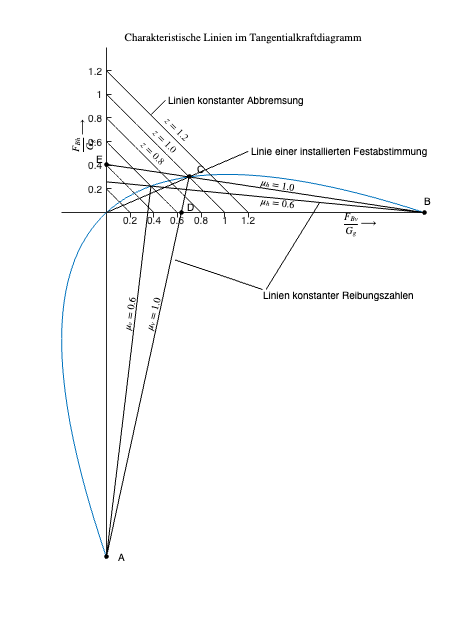

axis equal
ylim([Ay, 1.4])
xlim([-inf, Bx])
xticks(0.2:0.2:1.2);
yticks(0.2:0.2:1.2);
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
text(2, -0.1, "$\frac{F_{Bv}}{G_g} \longrightarrow$", "Interpreter", "latex");
text(-0.2, 0.5, "$\frac{F_{Bh}}{G_g} \longrightarrow$", "rotation", 90, "Interpreter", "latex");
title("Charakteristische Linien im Tangentialkraftdiagramm", 'Interpreter','latex')
ax.XRuler.TickLabelGapOffset = -15;
% Größe anpassen
pos = get(gcf, 'position');
pos(4) = 1000;
pos(3) = pos(4) * 3 / 4;
set(gcf, 'position', pos);
hold off

## Querdynamik

### Lineare Übertragungsfunktion

Für die Berechnung des Eigenwinkelgradienten $EG$ und des Schwimmwinkelgradienten $SG$ werden die Parameter ${C_v}^*$ und ${C_h}^*$ benötigt, die mit folgenden Formeln berechnet werden:

${C_v}^*=\frac{C_v}{F_{nv}}$ und ${C_h}^*=\frac{C_h}{F_{nh}}$

Cv_stern = Cv / Fnv;
Ch_stern = Ch / Fnh;

Der Eigenwinkelgradient $EG$ berechnet sich mit $EG=\frac{1}{g}*(\frac{1}{{C_v}^*}-\frac{1}{{C_h}^*})$

EG = (1/g) * (1/Cv_stern - 1/Ch_stern)

EG = 0.0058

Der Schwimmwinkelgradient $SG$ berechnet sich mit $SG=\frac{1}{g*{C_h}^*}$

SG = 1/(g * Ch_stern)

SG = 0.0050

Geschwindigkeit $v=60\frac{km}{h}$ in $m/s$ umwandeln:

v = 60 / 3.6;

Für $\omega_0^2$, $T_Z$, $2\sigma$ und $K$/$\omega_0^2$ werden jeweils die 3 Formeln aus dem Skript verwendet und die Ergebnisse verglichen. Aufgrund der Fließkommaungenauigkeit kann hierbei kein direkter Vergleich erfolgen. Die Ergebnisse werden daher mit einer Toleranz von $10^{-13}$verglichen. 

Ungedämpfte Eigenfrequenz $\omega_0^2$ und $\omega_0$ berechnen:

omega_0_quadrat_1 = (m * v^2 * (Ch * Lh - Cv * Lv) + Cv * Ch * L^2) / (J  * m * v^2);
omega_0_quadrat_2 = (m * Lv * Lh) / (SG * J * L *v^2) * (L + EG * v^2)/(EG + SG);
omega_0_quadrat_3 = (m * g * Lv * Lh) / (J * L * v^2) * (v^2 * (Ch_stern - Cv_stern) + g * L * Cv_stern * Ch_stern);

tolerance = 10^-13;
if abs(omega_0_quadrat_3-omega_0_quadrat_2) < tolerance && abs(omega_0_quadrat_1-omega_0_quadrat_2) < tolerance
    fprintf("Alle Berechnungs-Optionen ergeben den gleichen Wert für die Ungedämpfte Eigenfrequenz: %f", omega_0_quadrat_1)
end

Alle Berechnungs-Optionen ergeben den gleichen Wert für die Ungedämpfte Eigenfrequenz: 115.161290


omega_0 = sqrt(omega_0_quadrat_1);

Zählerzeitkonstante $T_Z$ berechnen:

Tz_1 = v * SG;
Tz_2 = (m * v *Lv) / (Ch * L);
Tz_3 = v / (Ch_stern * g);
if abs(Tz_3-Tz_2) < tolerance && abs(Tz_1-Tz_2) < tolerance
    fprintf("Alle Berechnungs-Optionen ergeben den gleichen Wert für die Zählerzeitkonstante: %f", Tz_1)
end

Alle Berechnungs-Optionen ergeben den gleichen Wert für die Zählerzeitkonstante: 0.082667

Abklingkonstante $2\sigma$ und $\sigma$ berechnen:

zwei_sigma_1 = (m * (Cv * Lv^2 + Ch * Lh^2) + J * (Cv + Ch)) / (J * m * v);
zwei_sigma_2 = (m * Lv * Lh * (EG * Lh + SG * L) + J * (EG * Lv + SG * L)) / (J * SG * L * v * (EG + SG));
zwei_sigma_3 = g * (m * Lv * Lh * (Cv_stern * Lv + Ch_stern * Lh) + J * (Cv_stern * Lh + Ch_stern * Lv)) / (J * L *v);
if abs(zwei_sigma_3-zwei_sigma_2) < tolerance && abs(zwei_sigma_1-zwei_sigma_2) < tolerance
    fprintf("Alle Berechnungs-Optionen ergeben den gleichen Wert für die Abklingkonstante: %f", zwei_sigma_1)
end

Alle Berechnungs-Optionen ergeben den gleichen Wert für die Abklingkonstante: 18.426797

sigma = zwei_sigma_1 / 2

sigma = 9.2134

Stationäre Gierverstärkung $K$/$\omega_0^2$  berechnen:

K_omega_0_quadrat_1 = (Cv * Ch *L) / (J * m * v * omega_0_quadrat_1);
K_omega_0_quadrat_2 = v / (L + EG * v^2);
K_omega_0_quadrat_3 = (Cv_stern * Ch_stern * g^2 * Lv * Lh * m)/(J * L * v * omega_0_quadrat_1);
if abs(K_omega_0_quadrat_3-K_omega_0_quadrat_2) < tolerance && abs(K_omega_0_quadrat_1-K_omega_0_quadrat_2) < tolerance
    fprintf("Alle Berechnungs-Optionen ergeben den gleichen Wert für die stationäre Gierverstärkung: %f", K_omega_0_quadrat_1)
end

Alle Berechnungs-Optionen ergeben den gleichen Wert für die stationäre Gierverstärkung: 3.781513

Gierdämpfungsmaß $D$ berechnen:

D_gier_1 = sigma / omega_0

D_gier_1 = 0.8586

Für die Darstellung der ungedämpften Eigenfrequenz, der gedämpften Eigenfrequenz und des Gierdämpfungsmaßes über der Geschwindigkeit nach Abbildung 1.47 werden $K$/$\omega_0^2$ , $2\sigma$, $\sigma$, $\omega_0^2$, $\omega_0$ und $D$ für den definierten Geschwindigkeitsbereich $[0 .. 250] \frac{km}{h}$ berechnet.

v_kmh = linspace(0, 250, 251);
v = v_kmh ./ 3.6;
zwei_sigma = (m * (Cv * Lv^2 + Ch * Lh^2) + J * (Cv + Ch)) ./ (J * m * v);
sigma = zwei_sigma / 2;
omega_0_quadrat = (m .* v.^2 * (Ch * Lh - Cv * Lv) + Cv * Ch * L^2) ./ (J * m .* v.^2);
omega_0 = sqrt(omega_0_quadrat);
K_omega_0_quadrat = (Cv * Ch * L) ./ (J .* m .* v .* omega_0_quadrat);
D_gier = sigma ./ omega_0;

Die ungedämpfte Eigenfrequenz $\nu_0$ berechnet sich mit der folgenden Formel:


$$\nu_0=\frac{\omega_0}{2\pi}$$


ny_0 = omega_0 / (2 * pi);

Die gedämpfte Eigenfrequenz $\nu$ berechnet sich mit der folgenden Formel:


$$\nu=\nu_0\sqrt{1-D^2}$$


ny = ny_0 .* sqrt(1 - D_gier.^2);

Die Werte sind teilweise imaginär und werden daher mit dem *find*- und *real-*Befehl auf Realwerte beschränkt.

Darstellung der ungedämpften und gedämpften Eigenfrequenz über der Geschwindigkeit nach *Abbildung 1.47*:

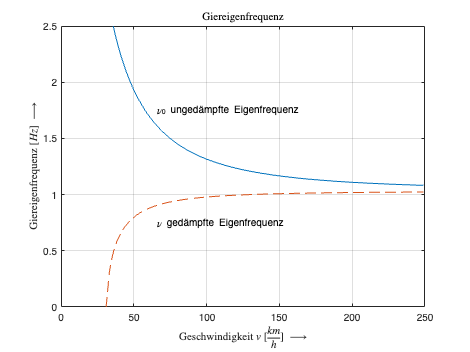

index = find(real(ny) > 0, 1);
figure
box on
hold on
plot(real(v_kmh(index-1:250)), real(ny_0(index-1:250)))
plot(real(v_kmh(index-1:250)), real(ny(index-1:250)), '--')
title('Giereigenfrequenz', 'Interpreter','latex')
ylim([0 2.5])
xlim([0 250])
xlabel('Geschwindigkeit $v$ $[\frac{km}{h}]$ $\longrightarrow$','Interpreter','latex');
ylabel('Giereigenfrequenz $[Hz]$ $\longrightarrow$','interpreter','latex')
text(65, 1.75, '\nu_0 ungedämpfte Eigenfrequenz');
text(65, 0.75, "\nu gedämpfte Eigenfrequenz");
grid
hold off

Darstellung des Dämpfungsmaßes über der Geschwindigkeit nach *Abbildung 1.47*:

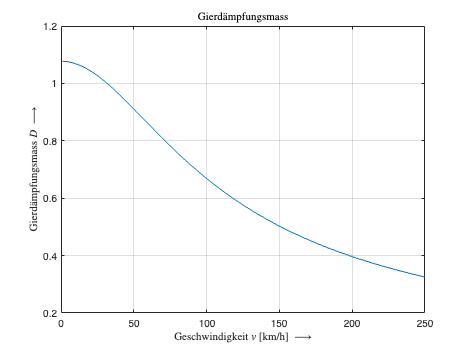

plot(v_kmh, D_gier)
box on
title('Gierd\"ampfungsmass', 'Interpreter','latex')
xlabel('Geschwindigkeit $v$ [km/h] $\longrightarrow$','Interpreter','latex');
ylabel('Gierd\"ampfungsmass $D$ $\longrightarrow$','interpreter','latex')
ylim([0.2 1.2])
yticks(0.2:0.2:1.2)
xlim([0 250])
grid

### Lenkradwinkelsprung  

#### Sprungantwort

Für die Berechnung der Sprungantwort wird zunächst die Übertragungsfunktion $G(s)$ definiert:


$$G(s) = \frac{\dot{\psi}(s)}{\delta(s)} = K \cdot \frac{1 + T_zs}{s^2+2\sigma s + \omega_0^2}$$


v = 60 / 3.6;
K = (Ch*Cv*L)/(J*m*v);
tf_gs = tf([Tz_1*K K], [1 zwei_sigma_1, omega_0_quadrat_1]);

Daraufhin wird mithilfe der *step*-Funktion von Matlab die Sprungantwort berechnet:

config = RespConfig('Amplitude', 45/iS);
[y_out, t_out] = step(tf_gs, 1.0, config);

#### Nichtlineares Einspurmodell  

model = 'Lenkradwinkelsprung';
load_system(model)
simIn = Simulink.SimulationInput(model);

*Hinweis: Alle Modellparameter, die mit *setModelParameter() *gesetzt werden können, lassen sich folgendermaßen ermitteln:*

Konfiguration der Simulation: $t_\text{Start}=0$, $t_\text{Stop}=t_{\rm end}$, Integration mit fester Zeitschrittweite $\Delta t=0.01$  

tend = 1;
simIn = setModelParameter(simIn,...
    'SolverType','Fixed-step',...
    'FixedStep','0.01',...
    'StartTime','0',...
    'StopTime',num2str(tend));

Konfiguration des Lenkradwinkelsprungs mit $\delta_\text{H}=45\degree $ und $v=60\text{ km/h}$

dH = 45;
v = 60;
simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/dH","Time",'0');         % Sprung bei t=0
simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/dH","After",string(dH)); % Sprunghöhe in Grad
simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/v","Value",string(v));   % Konstante Geschwindigkeit in km/h

Konfiguration der Pacejka-Blöcke mit den Schräglaufsteifikgeiten $C_\text v$, $C_\text h$ und den Achslasten $F_\text{nv}$, $F_\text{nh}$

simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/Einspurmodell/Reifenkräfte/Cv", "Value",string(Cv));
simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/Einspurmodell/Reifenkräfte/Ch", "Value",string(Ch));
simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/Einspurmodell/Reifenkräfte/Fnv","Value",string(Fnv));
simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/Einspurmodell/Reifenkräfte/Fnh","Value",string(Fnh));
applyToModel(simIn) % nicht unbedingt notwendig

Lenkradwinkelsprung simulieren

out = sim(simIn);

Daten auslesen

outputs = out.yout;
outputPsip = getElement(outputs,'psip');
t    = outputPsip.Values.Time;
psip = outputPsip.Values.Data;

Darstellung der Giergeschwindigkeit $\dot\psi$ über $t$ des nichtlinearen und des linearen Einspurmodells 

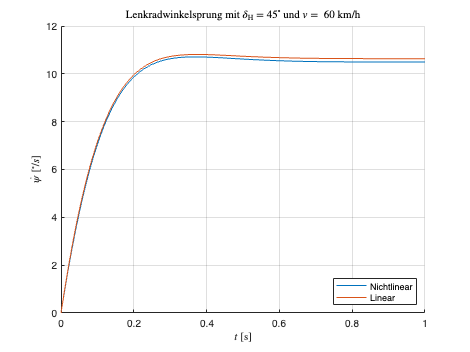

figure
hold on
plot(t,psip)
plot(t_out, y_out)
xlabel('$t$ [s]','Interpreter','latex');
ylabel('$\dot{\psi}$ $[^\circ/s]$','interpreter','latex')
title (['Lenkradwinkelsprung mit $\delta_{\rm H} = $' num2str(dH) '$^\circ$ und $v =$ ' num2str(v) ' km/h'] , 'Interpreter','latex'  )
legend('Nichtlinear','Linear','Location','southeast')
grid
hold off

### Seitenkräfte

**Neutral steuerndes Einspurmodell**

Es gilt $EG=0$. Für die Schräglaufsteifigkeit $C_{h,0}$ gilt damit: 


$$C_{h,0} = F_{nh} * {C_h}^* = F_{nh} * \frac{1}{\frac{F_{nv}}{C_v} - g * 0} = F_{nh} * \frac{1}{\frac{F_{nv}}{C_v}} = F_{nh} * \frac{C_v}{F_{nv}}$$


Ch_0 = Fnh * (Cv / Fnv)

Ch_0 = 6.9231e+04


$$C_{h,0} = 69231 \frac{N}{rad}$$


**Übersteuerndes Einspurmodell**

Es gilt $EG<0$. Für die Schräglaufsteifigkeit $C_{h,i}$ gilt damit: 

$C_{h,i} = F_{nh} * \frac{1}{\frac{F_{nv}}{C_v} - g *EG}$ und $C_{h,i} = B_h * F_{nh} * C * D$ mit $B_h \in [4...12]$

Durch Gleichsetzen und Umformen der beiden Gleichungen folgt:


$$EG = \frac{\frac{F_{nv}}{C_v} - \frac{1}{B_h*C*D}}{g}$$


Aus der Formel folgt, dass $B_h$ für einen möglichst weit im Negativ liegenden Eigenlenkwinkelgradienten $EG$ möglichst klein sein muss. Für $B_h \in [4...12]$ gilt daher $B_h = 4$.

EG_i = ((Fnv / Cv) - 1 / (4 * C * D)) / g

EG_i = -0.0027

Für die Schräglaufsteifigkeit $C_{h,i}$ gilt damit:

Ch_i = Fnh * (1 / (Fnv / Cv - g * EG_i))

Ch_i = 5.5470e+04


$$C_{h,i} = 55470 \frac{N}{rad}$$


#### **Darstellung der Seitenkräfte**

Mit den berechneten Werte $C_v$, $C_h$, $C_{h,0}$ und $C_{h,i}$ lassen sich die Seitenkräfte für die Achslasten $F_{nv}$ und $F_{nh}$ in Abhängigkeit vom Schräglaufwinkel im Bereich $\alpha \in [0^\circ...20^\circ]$ berechnen. 

Für die Berechnung der Seitenkräfte $F_s$ wird die Pacejka-Funktion des Simulink Modells *Lenkradwinkelsprung *verwendet.

alpha = linspace(0,20,100);
alpha_rad = alpha * pi / 180;
Fs_v = Pacejka(alpha_rad, Fnv, Cv, C, D, E);
Fs_h = Pacejka(alpha_rad, Fnh, Ch, C, D, E);
Fs_h_0 = Pacejka(alpha_rad, Fnh, Ch_0, C, D, E);
Fs_h_i = Pacejka(alpha_rad, Fnh, Ch_i, C, D, E);

Damit ergibt sich für die Seitenkäfte $F_s$ über dem Schräglaufwinkel $\alpha \in [0^\circ...20^\circ]$ folgendes DIagramm:

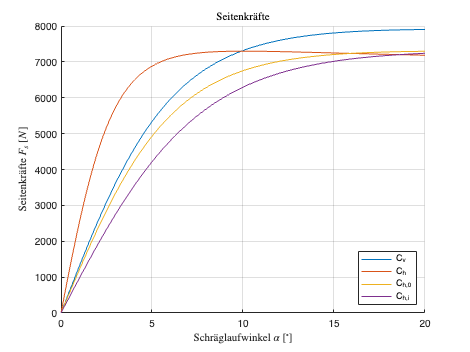

figure
hold on
plot(alpha, Fs_v, "DisplayName", "C_v")
plot(alpha, Fs_h, "DisplayName", "C_h")
plot(alpha, Fs_h_0, "DisplayName", "C_{h,0}")
plot(alpha, Fs_h_i, "DisplayName", "C_{h,i}")
title('Seitenkr\"afte', 'Interpreter', 'latex')
xlabel('Schr\"aglaufwinkel $\alpha$ $[^\circ]$', 'Interpreter', 'latex')
ylabel('Seitenkr\"afte $F_s$ $[N]$', 'Interpreter', 'latex')
grid
legend('show', 'Location', 'southeast')
hold off

### Gesteuerte stationäre Kreisfahrt

Simulation einer gesteuerten stationären Kreisfahrt mit konstanter Geschwindigkeit $v=60\frac{km}{h}$ und $\dot\delta_H = 1\frac{\degree }{s}$

v = 60 / 3.6;

Für die Simulation wird das Simulink-Modell *Kreisfahrt* verwendet.

model = 'Kreisfahrt';
load_system(model);
simIn = Simulink.SimulationInput(model);
simIn = setModelParameter(simIn,...
    'SolverType', 'Fixed-step',...
    'FixedStep', '0.01', ...
    'StartTime', '0',...
    'StopTime', '360');
simIn = setBlockParameter(simIn,"Kreisfahrt/Einspurmodell/Reifenkräfte/Cv", "Value",string(Cv));
simIn = setBlockParameter(simIn,"Kreisfahrt/Einspurmodell/Reifenkräfte/Fnv","Value",string(Fnv));
simIn = setBlockParameter(simIn,"Kreisfahrt/Einspurmodell/Reifenkräfte/Fnh","Value",string(Fnh));

Für das lineare Einspurmodell gilt folgende Formel für Lenkradwinkel $\delta_{H,lin}$:


$$\delta_{H,lin} = a_y * (\frac{l}{v^2} + EG) * i_S * \frac{180^\circ}{\pi}$$


Die Formel ist in der Funktion gesteuerte_kreisfahrt implementiert.

**Modellvariante 1: EG**

Für die erste Modellvariante wird der Eigenwinkelgradient $EG=0.0058$ mit der Schräglauftsteifigkeit $C_h$ verwendet.

simIn = setBlockParameter(simIn,"Kreisfahrt/Einspurmodell/Reifenkräfte/Ch", "Value",string(Ch));
out = sim(simIn);
outputs = out.yout;
ay_output = outputs{1}.Values.Data;
dH_output = outputs{2}.Values.Data;

ay = downsample(ay_output, round(length(ay_output)/250));
dH = downsample(dH_output, round(length(dH_output)/250));
ay_lin = linspace(0, 10, 100);
dH_lin = gesteuerte_kreisfahrt(ay_lin, L, v, EG, iS);

Darstellen der Lenkradwinkel $\delta_H$ und $\delta_{H,lin}$:

figure
hold on
plot(ay, dH, 'b')
plot(ay_lin, dH_lin, 'b--')

**Modellvariante 2: EG = 0**

Für die zweite Modellvariante wird der Eigenwinkelgradient $EG=0$ mit der Schräglauftsteifigkeit $C_{h,0} = 69231 \frac{N}{rad}$ verwendet.

simIn = setBlockParameter(simIn,"Kreisfahrt/Einspurmodell/Reifenkräfte/Ch", "Value",string(Ch_0));
out = sim(simIn);
outputs = out.yout;

ay_output = outputs{1}.Values.Data;
dH_output = outputs{2}.Values.Data;

ay = downsample(ay_output, round(length(ay_output)/250));
dH = downsample(dH_output, round(length(dH_output)/250));

dH_lin = gesteuerte_kreisfahrt(ay_lin, L, v, 0, iS);

Darstellen der Lenkradwinkel $\delta_{H,0}$ und $\delta_{H,0,lin}$:

plot(ay, dH, 'g')
plot(ay_lin, dH_lin, 'g--')

**Modellvariante 3: EG < 0**

Für die dritte Modellvariante wird der Eigenwinkelgradient $EG=-0.0027$ mit der Schräglauftsteifigkeit $C_{h,i} = 55470 \frac{N}{rad}$ verwendet.

simIn = setBlockParameter(simIn,"Kreisfahrt/Einspurmodell/Reifenkräfte/Ch", "Value",string(Ch_i));
out = sim(simIn);
outputs = out.yout;

ay_output = outputs{1}.Values.Data;
dH_output = outputs{2}.Values.Data;

ay = downsample(ay_output, round(length(ay_output)/250));
dH = downsample(dH_output, round(length(dH_output)/250));

dH_lin = gesteuerte_kreisfahrt(ay_lin, L, v, EG_i, iS);

Darstellen der Lenkradwinkel $\delta_{H,i}$ und $\delta_{H,i,lin}$:

plot(ay, dH, 'r')
plot(ay_lin, dH_lin, 'r--')

Diagramm beschriften:

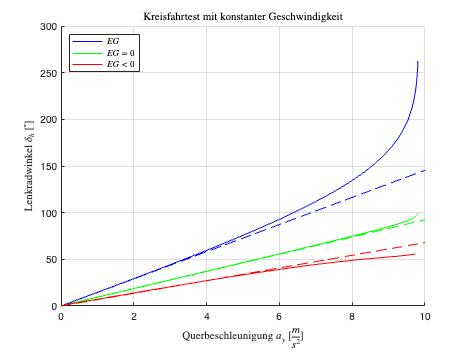

grid
title("Kreisfahrtest mit konstanter Geschwindigkeit", 'Interpreter', 'latex')
xlabel('Querbeschleunigung $a_y$ $[\frac{m}{s^2}]$', 'Interpreter', 'latex')
ylabel('Lenkradwinkel $\delta_h$ $[^\circ]$', 'Interpreter', 'latex')
legend({'$EG$', '', '$EG=0$', '', '$EG<0$', ''}, 'Interpreter', 'latex', 'Location', 'northwest')
hold off

### Geregelte stationäre Kreisfahrt

#### Regler parametrieren

Mit einer Bandbreite von $10\frac{rad}{s}$ und dem Parameter Phase Margin von $77.32^\circ$ sind die Anforderungen Overshoot = 0 und SettlingMax = 1 erfüllt.

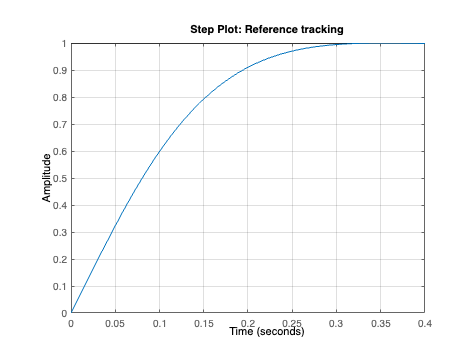

% Define options for pidtune command
opts = pidtuneOptions('PhaseMargin',77.32);

% PID tuning algorithm for linear plant model
[C2,pidInfo] = pidtune(tf_gs,'PI',10,opts);

% Clear Temporary Variables
clear opts

% Get desired loop response
Response = getPIDLoopResponse(C2,tf_gs,'closed-loop');

% Plot the result
stepplot(Response)
title('Step Plot: Reference tracking')
grid on


% Display system response characteristics
disp(stepinfo(Response))

         RiseTime: 0.1790
    TransientTime: 0.2646
     SettlingTime: 0.2646
      SettlingMin: 0.9016
      SettlingMax: 1.0000
        Overshoot: 0
       Undershoot: 0
             Peak: 1.0000
         PeakTime: 0.3527




% Clear Temporary Variables
clear Response

#### Simulink-Modell

Das Simulink-Modell Geregelte_Kreisfahrt simuliert eine Kreisfahrt mit konstantem Radius. Das Modell regelt die vorgegebene Soll-Giergeschwindigkeit $\dot\psi$ mit $\delta_H$als Ausgangsgröße mit $v = \sqrt{a_y*R$ und $\dot\psi_{soll}=\frac {a_y} v$ ein.

model = 'Geregelte_Kreisfahrt';
load_system(model);
simIn = Simulink.SimulationInput(model);
simIn = setModelParameter(simIn,...
    'SolverType', 'Fixed-step',...
    'FixedStep', '0.01', ...
    'StartTime', '0',...
    'StopTime', '360');
simIn = setBlockParameter(simIn,"Geregelte_Kreisfahrt/Einspurmodell/Reifenkräfte/Cv", "Value",string(Cv));
simIn = setBlockParameter(simIn,"Geregelte_Kreisfahrt/Einspurmodell/Reifenkräfte/Fnv","Value",string(Fnv));
simIn = setBlockParameter(simIn,"Geregelte_Kreisfahrt/Einspurmodell/Reifenkräfte/Fnh","Value",string(Fnh));

Der Radius $R$ wird auf $42.5 m$ gesetzt. 

R = 42.5;
simIn = setBlockParameter(simIn,"Geregelte_Kreisfahrt/Radius", "Value",string(R));

Die Beschleunigung $a_y$ startet bei $0.2\frac{m}{s^2}$ und wird alle $5s$ um $\Delta a_y = 0.2\frac{m}{s^2}$ bis $10\frac{m}{s^2}$ erhöht.

accel_y = linspace(0.2,10,50);
simIn = setBlockParameter(simIn, "Geregelte_Kreisfahrt/accel_y", "OutValues", mat2str(accel_y));

Für den PI-Regler werden die mithilfe des Task *Tune PID Controller *ermittelten Werte $C2.Kp$ und $C2.Ki$ für $P$ und $I$ gesetzt.

simIn = setBlockParameter(simIn, "Geregelte_Kreisfahrt/PI_Controller", "P", num2str(C2.Kp));
simIn = setBlockParameter(simIn, "Geregelte_Kreisfahrt/PI_Controller", "I", num2str(C2.Ki));

Für das lineare Einspurmodell gilt folgende Formel für Lenkradwinkel $\delta_{H,lin}$:


$$\delta_{H,lin} = (\frac{l}{R} + EG*a_y) * i_S * \frac{180^\circ}{\pi}$$


Die Formel ist in der Funktion geregelte_kreisfahrt implementiert.

**Modellvariante 1: EG**

Für die erste Modellvariante wird der Eigenwinkelgradient $EG=0.0058$ mit der Schräglauftsteifigkeit $C_h$ verwendet.

simIn = setBlockParameter(simIn,"Geregelte_Kreisfahrt/Einspurmodell/Reifenkräfte/Ch", "Value",string(Ch));
out = sim(simIn);
outputs = out.yout;

ay_output = outputs{1}.Values.Data;
dH_output = outputs{2}.Values.Data;

ay = downsample(ay_output, round(length(ay_output)/250));
dH = downsample(dH_output, round(length(dH_output)/250));

ay_lin = linspace(0, 10, 100);
dH_lin = geregelte_kreisfahrt(ay_lin, L, R, EG, iS);

Darstellen der Lenkradwinkel $\delta_{H,0}$ und $\delta_{H,0,lin}$:

figure
hold on
plot(ay, dH, 'b')
plot(ay_lin, dH_lin, 'b--')

**Modellvariante 2: EG = 0**

Für die zweite Modellvariante wird der Eigenwinkelgradient $EG=0$ mit der Schräglauftsteifigkeit $C_{h,0} = 69231 \frac{N}{rad}$ verwendet.

simIn = setBlockParameter(simIn,"Geregelte_Kreisfahrt/Einspurmodell/Reifenkräfte/Ch", "Value",string(Ch_0));
out = sim(simIn);
outputs = out.yout;

ay_output = outputs{1}.Values.Data;
dH_output = outputs{2}.Values.Data;

ay = downsample(ay_output, round(length(ay_output)/250));
dH = downsample(dH_output, round(length(dH_output)/250));

dH_lin = geregelte_kreisfahrt(ay_lin, L, R, 0, iS);

Darstellen der Lenkradwinkel $\delta_{H,0}$ und $\delta_{H,0,lin}$:

plot(ay, dH, 'g')
plot(ay_lin, dH_lin, 'g--')

**Modellvariante 3: EG < 0**

Für die dritte Modellvariante wird der Eigenwinkelgradient $EG=-0.0027$ mit der Schräglauftsteifigkeit $C_{h,i} = 55470 \frac{N}{rad}$ verwendet.

simIn = setBlockParameter(simIn,"Geregelte_Kreisfahrt/Einspurmodell/Reifenkräfte/Ch", "Value",string(Ch_i));
out = sim(simIn);
outputs = out.yout;

ay_output = outputs{1}.Values.Data;
dH_output = outputs{2}.Values.Data;

ay = downsample(ay_output, round(length(ay_output)/250));
dH = downsample(dH_output, round(length(dH_output)/250));

dH_lin = geregelte_kreisfahrt(ay_lin, L, R, EG_i, iS);

Darstellen der Lenkradwinkel $\delta_{H,0}$ und $\delta_{H,0,lin}$:

plot(ay, dH, 'r')
plot(ay_lin, dH_lin, 'r--')

Diagramm beschriften:

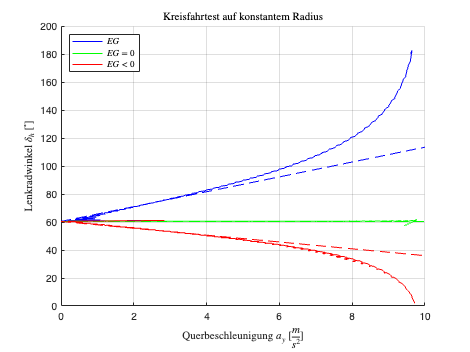

grid
title("Kreisfahrtest auf konstantem Radius", 'Interpreter', 'latex')
xlabel('Querbeschleunigung $a_y$ $[\frac{m}{s^2}]$', 'Interpreter', 'latex')
ylabel('Lenkradwinkel $\delta_h$ $[^\circ]$', 'Interpreter', 'latex')
legend({'$EG$', '', '$EG=0$', '', '$EG<0$', ''}, 'Interpreter', 'latex', 'Location', 'northwest')
hold off